close all;
clear variables;

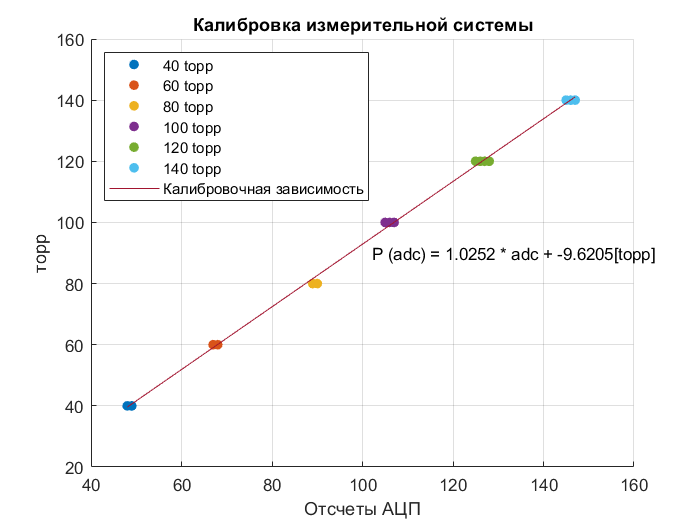

adc40 = fscanf(fopen('calibration_1.txt'), '%d');
adc60 = fscanf(fopen('calibration_2.txt'), '%d');
adc80 = fscanf(fopen('calibration_3.txt'), '%d');
adc100 = fscanf(fopen('calibration_4.txt'), '%d');
adc120 = fscanf(fopen('calibration_5.txt'), '%d');
adc140 = fscanf(fopen('calibration_6.txt'), '%d');
fclose('all');
torr40 = ones(length(adc40), 1) * 40;
torr60 = ones(length(adc60), 1) * 60;
torr80 = ones(length(adc80), 1) * 80;
torr100 = ones(length(adc100), 1) * 100;
torr120 = ones(length(adc120), 1) * 120;
torr140 = ones(length(adc140), 1) * 140;

cAdc = [adc40; adc60; adc80; adc100; adc120; adc140];
cTorr = [torr40; torr60; torr80; torr100; torr120; torr140];

c = polyfit(cAdc, cTorr, 1);
cFigure = figure('Name', 'Калибровка', "NumberTitle", 'off');

hold all;
plot(adc40, torr40, '.', 'MarkerSize', 20);
plot(adc60, torr60, '.', 'MarkerSize', 20);
plot(adc80, torr80, '.', 'MarkerSize', 20);
plot(adc100, torr100, '.', 'MarkerSize', 20);
plot(adc120, torr120, '.', 'MarkerSize', 20);
plot(adc140, torr140, '.', 'MarkerSize', 20);

plot(cAdc, polyval(c, cAdc));
legend('40 topp', '60 topp', '80 topp', '100 topp', '120 topp', '140 topp', 'Калибровочная зависимость', 'Location', 'northwest');
grid on;
xlabel('Отсчеты АЦП');
ylabel('торр');
title('Калибровка измерительной системы');
text(mean(cAdc) * 1.05, mean(cTorr), ['P (adc) = ', num2str(c(1)), ' * adc + ', num2str(c(2)), '[topp]']);
hold off;
saveas(cFigure, 'My.Калибровка.png');

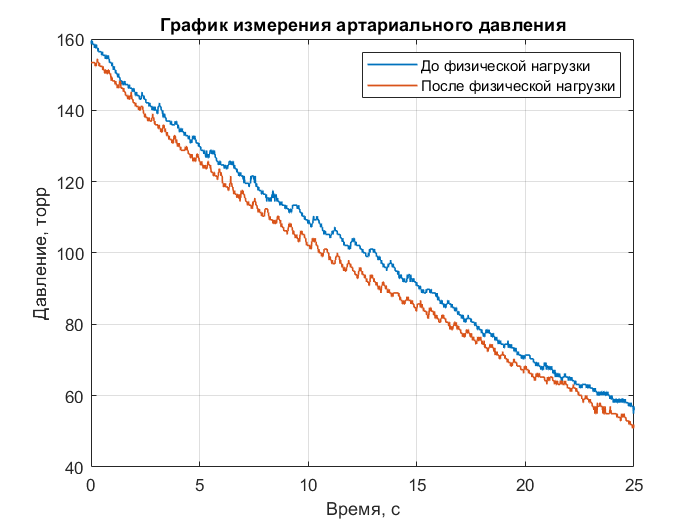

dt = 0.01;

adcBefore = fscanf(fopen('data_before.txt'), '%d');
tBefore = linspace(0, length(adcBefore) * dt, length(adcBefore));
pBefore = polyval(c, adcBefore);

adcAfter = fscanf(fopen('data_after.txt'), '%d');
tAfter = linspace(0, length(adcAfter) * dt, length(adcAfter));
pAfter = polyval(c, adcAfter);

pFigure = figure ('Name', 'Графики давления', 'NumberTitle', 'off');

plot(tBefore, pBefore, tAfter, pAfter, 'LineWidth', 1);
legend('До физической нагрузки', 'После физической нагрузки');

grid on;
xlim([0, 25]);

xlabel('Время, с');
ylabel('Давление, торр');
title('График измерения артариального давления');
hold off;
saveas(pFigure, 'My.Давление.png');

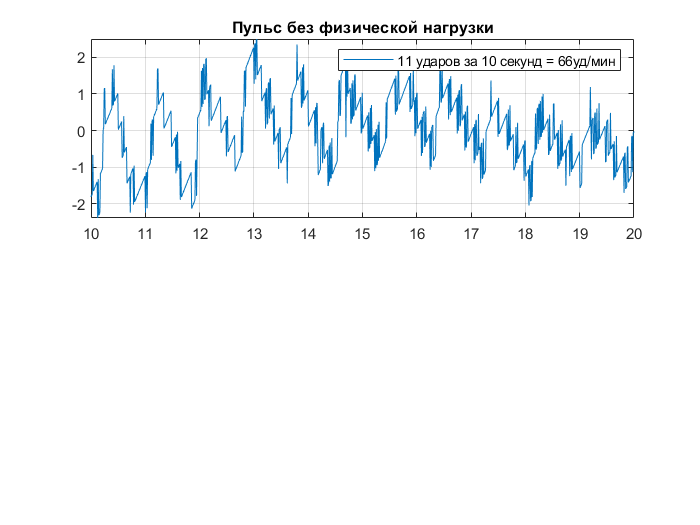

cBefore = polyfit(tBefore, pBefore, 7);
pulseBefore = pBefore - polyval(cBefore, tBefore)';
pulseFigure_1 = figure('Name', 'Графики пульса', 'NumberTitle','off');
subplot(2, 1, 1);
plot(tBefore, pulseBefore);
legend('11 ударов за 10 секунд = 66уд/мин');
grid on;
xlim([10 20]);
title('Пульс без физической нагрузки');
hold off;
saveas(pulseFigure_1, 'My.PulseBefore.png');

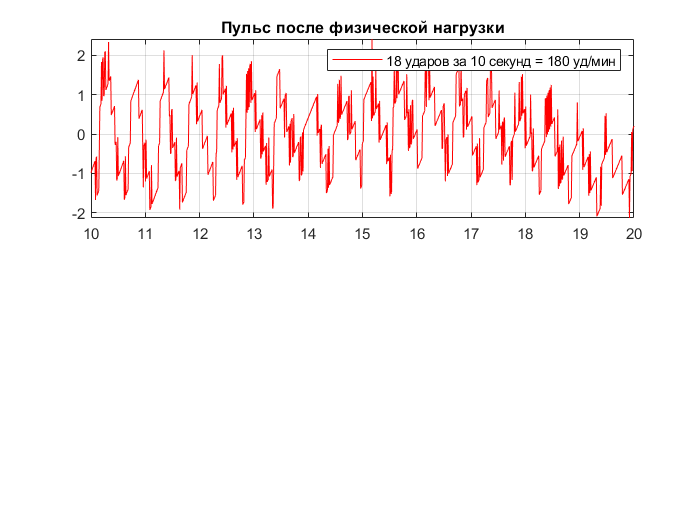

cAfter = polyfit(tAfter, pAfter, 5);
pulseAfter = pAfter - polyval(cAfter, tAfter)';
pulseFigure_2 = figure('Name', 'Графики пульса', 'NumberTitle','off');
subplot(2, 1, 1);
plot(tAfter, pulseAfter, 'r');
legend('18 ударов за 10 секунд = 180 уд/мин');
grid on;
xlim([10 20]);
title('Пульс после физической нагрузки');
saveas(pulseFigure_2, 'My.PulseAfter.png');